## **COOPERATIVE ROBOTS- project 04**

**GROUP 8: Aldovini, Elaamery, Pesavento **

warning('off');

## ROBOT dynamics

% constinuous system parameters
mass = 1;
inertia = 1;
n = 6;
m = 3;
A = [zeros(3,3), eye(3);
     zeros(3,3), zeros(3,3)]; % state matrix
B = [zeros(3,3); eye(3)];
C = eye(n);
D = zeros([n, m]);

% continuous-time system
plantc = ss(A,B,C,D);
% discrete-time system
Ts = 0.1; % sample time
plant = c2d(plantc, Ts, 'zoh'); % exact discretization

% initial state/position
x0 = [10; 14; 0; 0; 0; 0];

## Algorithm parameters

% proximity parameter to the goal position
delta = 0.1;

% COMMON PARAMETERS 
% weight for intermediate states
Q_weight = diag([1, 1, 10, 1, 1, 10]); 
% weight for inputs
R_weight = diag([0.9, 0.9, 0.9]); 
% weight for last state only
P_weight = diag([500, 500, 100, 100, 100, 100]);

% predictive horizon
if fixed_horizon
    N = N_fixed;
else
    N = N_long;
end

P = [1 0 0 0 0 0; 0 1 0 0 0 0]; % selects x and y

% Policy params
policy_halt = true;
k_loose_grip = 3;   % recovery policy horizon
% eps_loose_grip = 0.01; % formation error that triggers recovery policy

% LEADER PARAMETERS
% leader weights
leaderParams.Q = Q_weight*eye(n);       
leaderParams.R = R_weight*eye(m);
leaderParams.P = P_weight*eye(n);

% limit on leader acceleration, both x and y axes and angular acc
leaderParams.u_lim = 3; % [m/s^2]
leaderParams.phi_dot_lim = 10; % [rad/s^2]

% limit on leader velocity, both x and y axes
leaderParams.v_lim = 1; % [m/s]
leaderParams.w_lim = 1.57; % [rad/s]

% decay and cost parameters for obstacle distance
leaderParams.pot_decay = 10;
leaderParams.pot_cost = 15;

% visualization parameters
leaderParams.pos_color = "red";
leaderParams.pred_color = "magenta";
leaderParams.constraint_color = "yellow";
leaderParams.show_predictions = true;
leaderParams.show_constraints = true;
leaderParams.keep_predictions = false;

th = 0:0.2:2*pi;
% initial shape of leader
leaderParams.initRobotShape = 0.3*[-1, 1, 1, -1; -1, -1, 1, 1]; % square robot
% leaderParams.initRobotShape = [-0.01, 0.01, 0.01, -0.01; 0.8, 0.8, -0.8, -0.8]; % bar robot
% number of vertexes
[~, leaderParams.vertexes] = size(leaderParams.initRobotShape);
%leaderParams.robotShape = leaderParams.initRobotShape;
[~ , leaderParams.L] = size(leaderParams.initRobotShape);

% leader max radius
leaderParams.max_radius = max_radius(leaderParams.initRobotShape, leaderParams.vertexes) * 1.1;
% maximum distance for repulsive potential calculation
leaderParams.rep_dist_c = 3;
leaderParams.rep_dist = leaderParams.rep_dist_c * (leaderParams.max_radius + 0.5 * power(leaderParams.v_lim, 2) / leaderParams.u_lim);

% leader safety shape
leaderParams.dims = [max(leaderParams.initRobotShape(1, :)), max(leaderParams.initRobotShape(2, :))];
[leaderParams.max_axis, leaderParams.axis] = max(leaderParams.dims);
if leaderParams.dims(1) == leaderParams.dims(2) % square robot
    leaderParams.safe_shape = [leaderParams.max_radius * cos(th); leaderParams.max_radius * sin(th)];
    leaderParams.shape = "circle";
elseif leaderParams.axis == 1 % shape is longer in x
    leaderParams.a = leaderParams.max_axis*(1 + 0.2);
    leaderParams.b = sqrt(leaderParams.a^2 * leaderParams.initRobotShape(2,1)^2 / (leaderParams.a^2 - leaderParams.initRobotShape(1,1)^2));
    leaderParams.a = leaderParams.a * 1.1;
    leaderParams.b = leaderParams.b * 1.1;
    leaderParams.safe_shape = [leaderParams.a * cos(th); leaderParams.b * sin(th)];
    leaderParams.shape = "ellipse";
else % shape is longer in y
    leaderParams.b = leaderParams.max_axis*(1 + 0.2);
    leaderParams.a = sqrt(leaderParams.b^2 * leaderParams.initRobotShape(1,1)^2 / (leaderParams.b^2 - leaderParams.initRobotShape(2,1)^2));
    leaderParams.a = leaderParams.a * 1.1;
    leaderParams.b = leaderParams.b * 1.1;
    leaderParams.safe_shape = [leaderParams.a * cos(th); leaderParams.b * sin(th)];
    leaderParams.shape = "ellipse";
end


% FOLLOWER PARAMETERS
% relative distance from leader to follower to have (between the center of
% mass of the robots)
followerParams.d_FL = 1;

% relative cost for distance errors
followerParams.C = 5000; 

% limit on follower acceleration, to be higher than leader
followerParams.u_lim = 5; % [m/s^2]
followerParams.phi_dot_lim = 20; % [rad/s^2]

% limit on follower velocity, to be higher than leader
followerParams.v_lim = 1.5; % [m/s]
followerParams.w_lim = 3.14; % [rad/s]

% exponential decay of tracking quality over the prediction
followerParams.beta = 0.95;

% same obstacle avoidance parameters
followerParams.pot_decay = leaderParams.pot_decay;
followerParams.pot_cost = leaderParams.pot_cost;

% effort cost of follower
followerParams.R = diag([1, 1, 1]);

% visualization parameters
followerParams.pos_color = "blue";
followerParams.pred_color = "cyan";
followerParams.constraint_color = "green";
followerParams.show_predictions = true;
followerParams.show_constraints = true;
followerParams.keep_predictions = false;

% follower shape
followerParams.initRobotShape = 0.15*[-1, 1, 1, -1; -1, -1, 1, 1];
% number of vertexes of the robot not including load
[~, followerParams.vertexes] = size(followerParams.initRobotShape);

% load shape
followerParams.initLoadShape = (0.1*[-1, 1, 1, -1; -1, -1, 1, 1] ...
    +followerParams.d_FL*[-1, 0, 0, -1; 0, 0, 0, 0]);
followerParams.loadCenter = [-followerParams.d_FL/2; 0];

% robot shape contains the actual robot shape and the load shape
followerParams.robotShape = [followerParams.initRobotShape, followerParams.initLoadShape];
% number of vertexes of the robot including load
[~ , followerParams.L] = size(followerParams.robotShape);

% follower max radius
followerParams.max_radius = max_radius(followerParams.initRobotShape, followerParams.vertexes) * 1.1;
% maximum distance for repulsive potential calculation
followerParams.rep_dist_c = 3;
followerParams.rep_dist = followerParams.rep_dist_c * (followerParams.max_radius + 0.5 * power(followerParams.v_lim, 2) / followerParams.u_lim);

% follower safety shape
followerParams.dims = [max(followerParams.initRobotShape(1, :)), max(followerParams.initRobotShape(2, :))];
[followerParams.max_axis, followerParams.axis] = max(followerParams.dims);
if followerParams.dims(1) == followerParams.dims(2) % square robot
    followerParams.safe_shape = [followerParams.max_radius * cos(th); followerParams.max_radius * sin(th)];
elseif followerParams.axis == 1 % shape is longer in x
    followerParams.a = followerParams.max_axis*(1 + 0.2);
    followerParams.b = sqrt(followerParams.a^2 * followerParams.initRobotShape(2,1)^2 / (followerParams.a^2 - followerParams.initRobotShape(1,1)^2));
    followerParams.a = followerParams.a * 1.1;
    followerParams.b = followerParams.b * 1.1;
    followerParams.safe_shape = [followerParams.a * cos(th); followerParams.b * sin(th)];
else % shape is longer in y
    followerParams.b = followerParams.max_axis*(1 + 0.2);
    followerParams.a = sqrt(followerParams.b^2 * followerParams.initRobotShape(1,1)^2 / (followerParams.b^2 - followerParams.initRobotShape(2,1)^2));
    followerParams.a = followerParams.a * 1.1;
    followerParams.b = followerParams.b * 1.1;
    followerParams.safe_shape = [followerParams.a * cos(th); followerParams.b * sin(th)];
end

% perception range of the system, measured from load center
perception_range_c = 4;
perception_range = perception_range_c * (followerParams.d_FL/2 + max(leaderParams.max_radius, followerParams.max_radius));

## Obstacle parameters

% type of environment for papers
[x0, obstacles] = setupEnvironment(env_name);
[~, M] = size(obstacles);
% can be overridden, eventually set value for x0, and cell array obstacles

## Precompiled stuff for optimization

Not really that effective unless we compile the whole script

% precompiled follower elements
% THESE MATRIXES DEPEND ON THE VALUE OF N, IN ADAPTIVE ALGORITHM CAN CHANGE
% EVERY ITERATION, THEY NEED TO BE COMPUTED EVERY TIME
% NOW IN precomp_fixed_step TO BE EXECUTED WHEN FIXED_HORIZON
% followerParams.precompiledElements.Sd_bar = getSdbar(plant.A, plant.B, N);
% followerParams.precompiledElements.Td_bar = getTdbar(plant.A, N);
% followerParams.precompiledElements.S_bar = getSbar(plant.A, plant.B, N);
% followerParams.precompiledElements.T_bar = getTbar(plant.A, N);
% followerParams.precompiledElements.H1 = ...
%     followerParams.precompiledElements.S_bar'*followerParams.precompiledElements.S_bar;
% followerParams.precompiledElements.beta_vec = followerParams.beta .^ (0:(N-1))';
% followerParams.precompiledElements.N = N;

followerParams.precompiledElements.d = followerParams.d_FL;
followerParams.precompiledElements.C = followerParams.C;
followerParams.precompiledElements.L = followerParams.L;
followerParams.precompiledElements.M = length(obstacles);
followerParams.precompiledElements.beta = followerParams.beta;
followerParams.precompiledElements.P = P;
% followerParams.precompiledElements.P_bar = kron(eye(N), followerParams.precompiledElements.P);

leaderParams.precompiledElements.P = P;
% leaderParams.precompiledElements.P_bar = kron(eye(N), followerParams.precompiledElements.P);
% leaderParams.precompiledElements.Sd_bar = followerParams.precompiledElements.Sd_bar;
% leaderParams.precompiledElements.Td_bar = followerParams.precompiledElements.Td_bar;
% leaderParams.precompiledElements.S_bar = followerParams.precompiledElements.S_bar;
% leaderParams.precompiledElements.T_bar = followerParams.precompiledElements.T_bar;

## Initialization

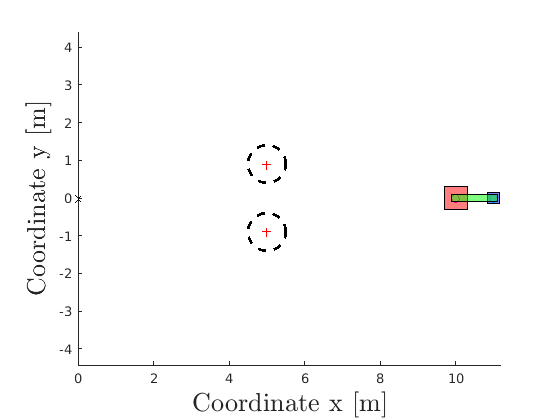

% variable meaning
% x_l, x_f = actual states of leader, follower
% X_L, X_L_stacked = preferred path by leader, 4xN and 4*Nx1 the stacked
% real_d = actual distance between robots

% goal state flag 
goal_reached = false;
i = 1;

% initialization leader and follower STATES
x_l(:,i) = x0;
x_f(:,i) = x0 + [followerParams.d_FL; 0; 0; 0; 0; 0]; % at initial condition we have horizontal disposition with d_FL distance

% vertexes change orientation because of phi
% apply rotation for both robots using the orientation
leaderParams.robotShape = Rmat(x_l(3,i))*leaderParams.initRobotShape;
followerParams.robotShape(:, 1:followerParams.vertexes) = Rmat(x_f(3,i))*followerParams.initRobotShape(:, 1:followerParams.vertexes);

% get the instantaneous rotation of load and apply to load and leader
loadTheta_ref(i) = 0;
loadTheta(i) = loadTheta_ref(i); % on the initial step we assume no error in agent position
followerParams.loadShape = Rmat(loadTheta_ref(i))*followerParams.initLoadShape;

% initialize robot distance, no error assumed on first step
real_d(i) = followerParams.d_FL;

% initial guesses for optimal inputs
U_l_old = zeros([m*N,1]);
U_f_old = zeros([m*N,1]);

% initialize obstacles
if not(sim_perception_range)
    obs_in_perception = obstacles;
end

figure(1); 
axis equal; hold on; grid on;
set(gcf,'Visible','on'); hold on; grid off;
sp = SystemPlotter(leaderParams, followerParams, x_l(:,1), x_f(:, 1), N, obstacles);
% sp = SystemPlotter(leaderParams, followerParams, x_l(:,1), [], N, obstacles);
%tit = title("\textbf{Iteration 1, time: 0s}","Interpreter","latex", "FontSize", 14);
%set(gca, 'XTick', [], 'YTick', []);
%set(gca, "FontSize", 20);
xlabel("Coordinate x [m]","Interpreter","latex", "FontSize", 20)
ylabel("Coordinate y [m]","Interpreter","latex", "FontSize", 20)

% xlim([-1, 15]);
% ylim([-5, 5]);
% xlim([0, 45]);
% ylim([0, 25]);

**MPC IMPLEMENTATION**

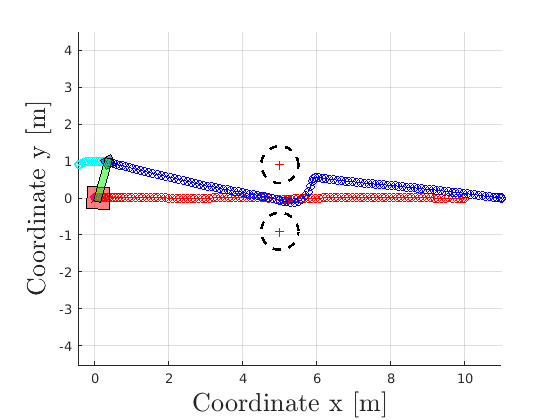

% initialization of fixed horizon
if fixed_horizon
    % N_fixed given by sim_file
    N = N_fixed;
    U_l_old = zeros([m*N,1]);
    U_f_old = zeros([m*N,1]);
    precomp_fixed_step;
end

% min_dist = inf;

while (~goal_reached) && (i < 1000) % terminal condition: goal reach & too much iterations for these environments
    tic

    % obstacles perception
    if sim_perception_range
        obs_in_perception = [];
        cnt = 1;
        for perc_index = 1:length(obstacles)
            if (norm(obstacles{perc_index}.center(:) - (x_f(1:2,i) + Rmat(loadTheta(i)) * followerParams.loadCenter)) - obstacles{perc_index}.radius) < perception_range
                obs_in_perception{cnt} = obstacles{perc_index}; % scanning obstacles sensed
                cnt = cnt + 1;
            end
        end
    end
    
    % getting q for each agent
    [qi_leader, d_leader] = getObstacleInfo(obs_in_perception, x_l(1:2, i));
    [~, M_leader(i)] = size(qi_leader);

    [qi_follower, d_follower] = getObstacleInfo(obs_in_perception, x_f(1:2, i));
    [~, M_follower(i)] = size(qi_follower);

    [q_load, ~] = getObstacleInfo(obs_in_perception, x_f(1:2, i) + Rmat(loadTheta(i)) * followerParams.loadCenter); % loadCenter rotates with load

    % if(min(d_leader) < min_dist)
    %     min_dist = min(d_leader);
    % end
    % 
    % if(min(d_follower) < min_dist)
    %     min_dist = min(d_follower);
    % end

    if fixed_horizon % fixed horizon always considers obstacles, so crit_dist = true always
        crit_dist = true;
    else
        % calculations of distances between obstacles for leader and follower
        d_l_min = min(d_leader);
        d_f_min = min(d_follower);
        
        % N_short and N_long given by sim_file
        
        % selection of the state of the algorithm
        if (M_leader(i) == 0) && (M_follower(i) == 0) % no obstacles
             crit_dist = false;
             N = N_long;
        elseif (d_l_min <= leaderParams.rep_dist) || (d_f_min <= followerParams.rep_dist)
            % agents near obstacles, enables obstacle avoidance, need to reduce
            % prediction horizon to be faster
            crit_dist = true;
            if N == N_long % pred horizon changed, need to adapt U_*_old
                N = N_short;
                % fixing the dimension of U_old to enable fmincon
                U_l_old = U_l_old(1:m*N);
                U_f_old = U_f_old(1:m*N);
            else
                N = N_short;
            end
        else 
            % agents far from obstacles, no need to provide for obstacle
            % avoidance, big prediction horizon 
            crit_dist = false;
            if N == N_short % pred horizon changed, need to adapt U_*_old
                N = N_long;
                % fixing the dimension of U_old to enable fmincon
                for s = (N_short + 1):N_long
                    U_l_old((m*(s-1) + 1):(m*(s-1) + 3)) = U_l_old((m*(N_short-1) + 1):(m*(N_short-1) + 3));
                    U_f_old((m*(s-1) + 1):(m*(s-1) + 3)) = U_f_old((m*(N_short-1) + 1):(m*(N_short-1) + 3));
                end
            else
                N = N_long;
            end
        end
    end

    % obtain the next state, the planned path, the identified qis and solver error for leader
    [x_l(:,i+1), X_L, ~, U_l_old] = leaderMPCandUpdate( ...
        plant, x_l(:, i), n, m, N, M_leader(i), leaderParams, obs_in_perception, qi_leader, U_l_old, crit_dist, fixed_horizon, alg_fmincon);
    
    % stack the planned path to supply to the follower, and have it do mpc
    X_L_stacked = reshape(X_L, [n*N, 1]);
    
    %LINEAR follower constraints:
    [x_f(:,i+1), X_F, ~, U_f_old] = followerMPCandUpdate(...
        plant, X_L_stacked, x_f(:, i), n, m, N, M_follower(i), q_load, followerParams, obs_in_perception, qi_follower, U_f_old, loadTheta(i), crit_dist, fixed_horizon, alg_fmincon);

    if policy_halt 
        % check if trajectory does not loose the load
        formation_error_allt = abs(vecnorm(P*(X_L-X_F))-followerParams.d_FL);
        if any(formation_error_allt(1:k_loose_grip) > eps_loose_grip)
            % obtain the next state, the planned path, the identified qis and solver error for leader
            [x_l(:,i+1), X_L, error, U_l_old] = leaderMPCandUpdateHalt( ...
                plant, x_l(:, i), n, m, N, M_leader(i), leaderParams, obs_in_perception, qi_leader, zeros([m*N,1]), crit_dist, fixed_horizon, alg_fmincon);

            % stack the planned path to supply to the follower, and have it do mpc
            X_L_stacked = reshape(X_L, [n*N, 1]);
            %LINEAR follower constraints:
            [x_f(:,i+1), X_F, ~, U_f_old] = followerMPCandUpdate(...
                plant, X_L_stacked, x_f(:, i), n, m, N, M_follower(i), q_load, followerParams, obs_in_perception, qi_follower, zeros([m*N,1]), loadTheta(i), crit_dist, fixed_horizon, alg_fmincon);
        end
    end

    % get the instantaneous rotation of load and apply to load and leader
    % -> REFERENCE
    % fl_diff = x_f(:, i+1) - x_l(:, i+1);
    % loadTheta_ref(i+1) = atan2(fl_diff(2), fl_diff(1));

    % real position of the robot is affected by measure noise, applied to
    % the agent state in following step
    x_l(:, i+1) = x_l(:, i+1) + meas_noise(sigma_2, sim_noise);
    x_f(:, i+1) = x_f(:, i+1) + meas_noise(sigma_2, sim_noise);

    % get the instantaneous rotation of load and apply to load and leader -> WITH NOISE
    fl_diff_noise = x_f(:, i+1) - x_l(:, i+1);
    loadTheta(i+1) = atan2(fl_diff_noise(2), fl_diff_noise(1));

    % check if goal was reached up to desired precision -> WITH NOISE
    if norm(x_l(1:2,i)) < delta
        goal_reached = true;
    end
    
    % distance between the 2 robots -> WITH NOISE
    real_d(i) = norm(x_l(1:2,i) - x_f(1:2,i));  

    if plotting 
        % do the plotting
        sp.updateLeaderPath(x_l(:,i), X_L);
        sp.updateLoadPos(x_l(:,i), x_f(:,i), loadTheta(i));
        sp.updateObstacles(obstacles, length(obstacles));
        sp.updateFollowerPath(x_f(:,i), X_F);
        tit.String = "Iteration: "+num2str((i))+", time: "+num2str((i)*Ts)+"s";
        sp.redraw();
        grid on;
    end

    %Obstacle dynamics 
    obstacles = obstacles_dynamics(obstacles, Ts, i);
    
    % execution time of the single step and state of the step
    execution_time(1, i) = toc; % [s]
    execution_time(2, i) = crit_dist;

    % update iteration
    i = i+1;
    
end

tot_ex_time = sum(execution_time(1, :));

## Result plot

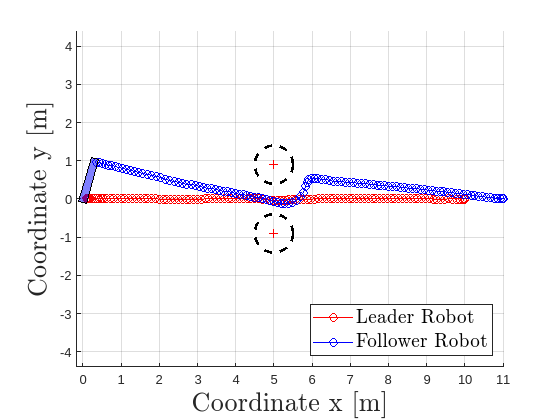

time = 0:Ts:Ts*(i-2);

followerParams.loadShape = Rmat(loadTheta(i-1))*followerParams.initLoadShape;

% Trajectory plot
traj = figure(2);  hold on; axis equal; grid on;
plot( x_l(1,1:(i-1)), x_l(2,1:(i-1)), "-o","Color", "red");
plot( x_f(1,1:(i-1)), x_f(2,1:(i-1)), "-o","Color", "blue")
plotObstacles(obstacles);
plot(...
   polyshape(x_f(1,end)+followerParams.loadShape(1,:),...
             x_f(2,end)+followerParams.loadShape(2,:)),...
   'FaceColor',followerParams.pos_color,'FaceAlpha',0.5);
%title("\textbf{Leader-Follower Trajectory}","Interpreter","latex", "FontSize", 14)
xlabel("Coordinate x [m]","Interpreter","latex", "FontSize", 20)
ylabel("Coordinate y [m]","Interpreter","latex", "FontSize", 20)
legend("Leader Robot","Follower Robot","Location","southeast","Interpreter","latex", "FontSize", 15)
exportgraphics(traj, traj_fig_name, 'Resolution', 300);

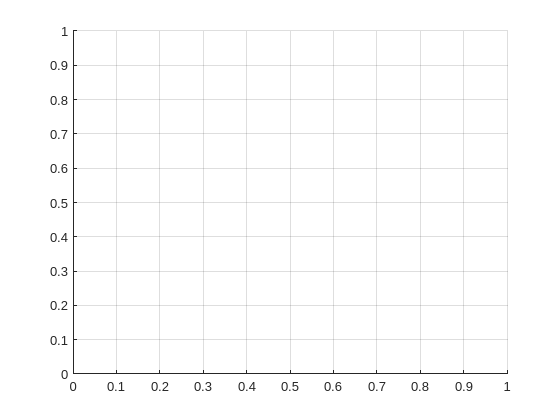


% Coordinates evolution and formation error plot
figure; 
hold on; grid on;

plot(time, x_l(1,1:(i-1)), "-b", "LineWidth", 2);

Error using plot
Vectors must be the same length.

plot(time, x_l(2,1:(i-1)), "Color", "black", "LineStyle", "-", "LineWidth", 2);
plot(time, x_f(1,1:(i-1)), "--r", "LineWidth", 2);
plot(time, x_f(2,1:(i-1)), "Color", "#FF00FF", "LineStyle", "--", "LineWidth", 2);
xlabel("Time [s]", "Interpreter","latex","FontSize", 20)
ylabel("$x$ \ $y$ [m]", "Interpreter","latex", "FontSize", 20)
%title("\textbf{Agents position evolution}", "Interpreter","latex", "FontSize", 14)
legend("$x^{L}$","$y^{L}$","$x^{F}$","$y^{F}$","Interpreter","latex", "FontSize", 15)

figure;
hold on; grid on;
plot(time, x_l(3,1:(i-1)), "-g", "LineWidth", 2);
plot(time, x_f(3,1:(i-1)), "Color", "#77AC30", "LineStyle", "-", "LineWidth", 2);
xlabel("Time [s]", "Interpreter","latex","FontSize", 14)
ylabel("$\theta$ [rad]", "Interpreter","latex", "FontSize", 14)
title("\textbf{Agents orientation evolution}", "Interpreter","latex", "FontSize", 14)
legend("$\theta_{L}$","$\theta_{F}$","Interpreter","latex", "FontSize", 12)



% formation error plot
figure;
hold on; grid on;
plot(time(1:end),real_d - followerParams.d_FL, "LineWidth", 2);
grid on;
% xlim([0, 20]);
ylim([-0.015, 0.015]);
xlabel("Time [s]", "Interpreter","latex", "FontSize", 20)
ylabel("$fe_{L,F}(t)$ [m]", "Interpreter","latex", "FontSize", 20)
%title("\textbf{Formation error}", "Interpreter","latex", "FontSize", 14)
% exportgraphics(coord, coord_fig_name, 'Resolution', 300);

% quadratic formation error
figure;
hold on; grid on;
plot(time(1:end),real_d.^2 - followerParams.d_FL^2, "LineWidth", 2);
grid on;
xlim([0, 20]);
ylim([-0.35, 0.35]);
xlabel("Time [s]", "Interpreter","latex", "FontSize", 20)
ylabel("$e_{L,F}(t)$ [m]", "Interpreter","latex", "FontSize", 20)


vel = figure;
hold on;
grid on;
plot(time, x_l(4,1:(i-1)), "-b", "LineWidth", 2);
plot(time, x_l(5,1:(i-1)), "Color", "black", "LineStyle", "-", "LineWidth", 2);
plot(time, x_f(4,1:(i-1)), "--r", "LineWidth", 2);
plot(time, x_f(5,1:(i-1)), "Color", "#FF00FF", "LineStyle", "--", "LineWidth", 2);
set(gca, "FontSize", 20);
xlabel("Time [s]", "Interpreter","latex","FontSize", 40)
ylabel("$v_x$/$v_y$ [m/s]", "Interpreter","latex", "FontSize", 40)
%title("\textbf{Agents velocity evolution}", "Interpreter","latex", "FontSize", 14)
legend("$v_{x}^L$","$v_{y}^L$","$v_{x}^F$","$v_{y}^F$","Interpreter","latex", "FontSize", 22)

figure;
hold on;
grid on;
plot(time, x_l(6,1:(i-1)), "-g", "LineWidth", 2);
plot(time, x_f(6,1:(i-1)), "Color", "#77AC30", "LineStyle", "-", "LineWidth", 2);
xlabel("Time [s]", "Interpreter","latex","FontSize", 14)
ylabel("$\omega$ [rad/s]", "Interpreter","latex", "FontSize", 14)
title("\textbf{Agents angular velocity evolution}", "Interpreter","latex", "FontSize", 14)
legend("$\omega_{L}$","$\omega_{F}$","Interpreter","latex", "FontSize", 12)

% exportgraphics(vel, vel_fig_name, 'Resolution', 300);


% DISTANCE BETWEEN AGENTS AND OBSTACLES PLOTTING
% leader
if M >= 1
    for j=1:leaderParams.L
        dist_l{j} = zeros(length(time), M);
    end
    for o=1:M
        for j=1:leaderParams.L
            for t=1:length(time)
                dist_l{j}(t,o)= norm((x_l(1:2, t)+Rmat(x_l(3,t))*leaderParams.initRobotShape(:, j)) - obstacles{o}.dynamics(:, t)) - obstacles{o}.radius;
            end
        end
    end
    for o = 1:M
        for j = 1:leaderParams.L
            dist_instant_l_min{j}(o) = min(dist_l{j}(:, o));
        end
    end
    for j = 1:leaderParams.L
        [dist_instant_l_min{j}, o_l] = min(dist_instant_l_min{j}(:));
        vis_vec_l(j) = dist_instant_l_min{j};
    end
    [~, v_l] = min(vis_vec_l);
    % for j=1:leaderParams.L
    %     figure;
    %     hold on;
    %     grid on;
    %     for o=1:M
    %         plot(time, dist_l{j}(:,o));
    %     end
    % end
    
    % follower 
    for j=1:followerParams.vertexes
        dist_f{j} = zeros(length(time), M);
    end
    for o=1:M
        for j=1:followerParams.vertexes
            for t=1:length(time)
                dist_f{j}(t,o)= norm((x_f(1:2, t)+Rmat(x_f(3,t))*followerParams.initRobotShape(:, j)) - obstacles{o}.dynamics(:, t)) - obstacles{o}.radius;
            end
        end
    end
    for o = 1:M
        for j = 1:followerParams.vertexes
            dist_instant_f_min{j}(o) = min(dist_f{j}(:, o));
        end
    end
    for j = 1:followerParams.vertexes
        [dist_instant_f_min{j}, o_f] = min(dist_instant_f_min{j}(:));
        vis_vec_f(j) = dist_instant_f_min{j};
    end
    [~, v_f] = min(vis_vec_f);
    % for j=1:followerParams.vertexes
    %     figure;
    %     hold on;
    %     grid on;
    %     for o=1:M
    %         plot(time, dist_f{j}(:,o));
    %     end
    % end
    
    % load 
    for j=1:(followerParams.L - followerParams.vertexes)
        dist_load{j} = zeros(length(time), M);
    end
    for o=1:M
        for j=1:(followerParams.L - followerParams.vertexes)
            for t=1:length(time)
                dist_load{j}(t,o)= norm((x_f(1:2, t)+Rmat(loadTheta(t))*followerParams.initLoadShape(:, j)) - obstacles{o}.dynamics(:, t)) - obstacles{o}.radius;
            end
        end
    end
    for o = 1:M
        for j=1:(followerParams.L - followerParams.vertexes)
            dist_instant_load_min{j}(o) = min(dist_load{j}(:, o));
        end
    end
    for j=1:(followerParams.L - followerParams.vertexes)
        [dist_instant_load_min{j}, o_load] = min(dist_instant_load_min{j}(:));
        vis_vec_load(j) = dist_instant_load_min{j};
    end
    [~, v_load] = min(vis_vec_load);
    % for j=(followerParams.vertexes + 1):followerParams.L
    %     figure;
    %     hold on;
    %     grid on;
    %     for o=1:M
    %         plot(time, dist_f{j}(:,o));
    %     end
    % end

    % min_obs_dist = min(min(dist_l{v_l}(:,o_l)), min(dist_f{v_f}(:,o_f)));

    min_obs_dist = min([min(horzcat(dist_l{:})), min(horzcat(dist_f{:}))]);

    if (min_obs_dist > 0)
        collision = false;
    else 
        collision = true;
    end
    obj_dist = figure;
    hold on;
    title("\textbf{Distance vertex-obstacle for the vertex where the minimum is reached [m]}", "Interpreter","latex","FontSize", 14);
    plot(time, dist_l{v_l}(:,o_l), "red", "LineWidth", 1.5);
    plot(time, dist_f{v_f}(:,o_f), "blue", "LineWidth", 1.5);
    plot(time, dist_load{v_load}(:,o_load), "green", "LineWidth", 1.5);
    legend("leader", "follower", "load", "Interpreter","latex","FontSize", 12);
    xlabel("Time [s]", "Interpreter","latex","FontSize", 14);
    ylabel("Distance [m]", "Interpreter","latex","FontSize", 14);
    % exportgraphics(obj_dist, obj_dist_fig_name, 'Resolution', 300);
end

% VERTEX POSITION PLOTTING
% vertex position leader
% time = 0:Ts:Ts*(i-1);
% v_rot_1 = zeros(2,length(time));
% v_rot_2 = zeros(2,length(time));
% v_rot_3 = zeros(2,length(time));
% v_rot_4 = zeros(2,length(time));
% figure;
% hold on;
% for k=1:length(time)
%     v_rot_1(1:2, k) = Rmat(x_l(3,k))*leaderParams.initRobotShape(:,1);
% end
% plot( x_l(1,1:i) + v_rot_1(1,:), x_l(2,1:i) + v_rot_1(2,:), "r");
% 
% for k=1:length(time)
%     v_rot_2(1:2, k) = Rmat(x_l(3,k))*leaderParams.initRobotShape(:,2);
% end
% plot( x_l(1,1:i) + v_rot_2(1,:), x_l(2,1:i) + v_rot_2(2,:), "g");
% 
% for k=1:length(time)
%     v_rot_3(1:2, k) = Rmat(x_l(3,k))*leaderParams.initRobotShape(:,3);
% end
% plot( x_l(1,1:i) + v_rot_3(1,:), x_l(2,1:i) + v_rot_3(2,:), "y");
% 
% for k=1:length(time)
%     v_rot_4(1:2, k) = Rmat(x_l(3,k))*leaderParams.initRobotShape(:,4);
% end
% plot( x_l(1,1:i) + v_rot_4(1,:), x_l(2,1:i) + v_rot_4(2,:), "b");
% xlabel("x [m]");
% ylabel("y [m]");
% legend("vertice 1 leader", "vertice 2 leader", "vertice 3 leader", "vertice 4 leader");


**TIME ANALYSIS**

[max_time_exe, max_time_pos] = max(execution_time(1, :));
max_time_status = execution_time(2, max_time_pos);
[min_time_exe, min_time_pos] = min(execution_time(1, :));
min_time_status = execution_time(2, min_time_pos);

% total mean time
mean_tot_time = tot_ex_time / (i-1);

% mean time for each state
sum0 = 0;
sum1 = 0;
count0 = 0;
count1 = 0;
for t = 1:(i-1)
    if execution_time(2,t) == 0
        sum0 = sum0 + execution_time(1,t);
        count0 = count0 + 1;
        et0(count0) = execution_time(1,t);
    else
        sum1 = sum1 + execution_time(1,t);
        count1 = count1 + 1;
        et1(count1) = execution_time(1,t);
    end
end
mean0 = sum0 / count0;
mean1 = sum1 / count1;

times = figure;
hold on; grid on;

% selection of bin dimension
binedges = [min_time_exe:0.01:max_time_exe max_time_exe];
if (length(binedges) > 150) && (length(binedges) < 600)
    binedges = [min_time_exe:0.05:max_time_exe max_time_exe];
    title("\textbf{Bin = 0.05 [s]}", "Interpreter","latex","FontSize", 14);
elseif (length(binedges) > 600) && (length(binedges) < 1200)
    binedges = [min_time_exe:0.25:max_time_exe max_time_exe];
    title("\textbf{Bin = 0.25 [s]}", "Interpreter","latex","FontSize", 14);
elseif (length(binedges) > 1200)
    binedges = [min_time_exe:0.5:max_time_exe max_time_exe];
    title("\textbf{Bin = 0.5 [s]}", "Interpreter","latex","FontSize", 14);
else 
    title("\textbf{Bin = 0.01 [s]}", "Interpreter","latex","FontSize", 14);
end

% histogram
if fixed_horizon || (count1 == 0)
    h = histogram(execution_time(1,:), binedges, "FaceColor", "blue");
    max_str = string(max_time_exe);
    min_str = string(min_time_exe);
    mean_str = string(mean_tot_time);
    text((max_time_exe + min_time_exe)/2, max(h.Values)/2, append("max = ", max_str, " [s]"), "FontWeight", "bold"); 
    text((max_time_exe + min_time_exe)/2, (max(h.Values)/2) - max(h.Values)/7, append("min = ", min_str, " [s]"), "FontWeight", "bold");
    text((max_time_exe + min_time_exe)/2, (max(h.Values)/2) - 2*max(h.Values)/7, append("mean = ", mean_str, " [s]"), "FontWeight", "bold");
else
    % stacked histogram for the adaptive method, showing performance of each state
    hist0 = histcounts(et0(:), binedges);
    hist1 = histcounts(et1(:), binedges);
    hist2 = hist0 + hist1;
    
    for bin = 1:(length(binedges) - 1)
        binc(bin) = (binedges(bin)+binedges(bin+1))/2;
    end
    
    bar(binc, hist2, 1, "grouped", "FaceColor", "red", "EdgeColor", "black");
    bar(binc, hist0, 1, "grouped", "FaceColor", "green", "EdgeColor", "black");
    
    legend("Short horizon + obstacle avoidance", "Long horizon", "Interpreter","latex","FontSize", 12);

    max_str = string(max_time_exe);
    min_str = string(min_time_exe);
    mean_str = string(mean_tot_time);
    text((max_time_exe + min_time_exe)/2, max(hist2)/2, append("max = ", max_str, " [s]"), "FontWeight", "bold"); 
    text((max_time_exe + min_time_exe)/2, (max(hist2)/2) - max(hist2)/7, append("min = ", min_str, " [s]"), "FontWeight", "bold");
    text((max_time_exe + min_time_exe)/2, (max(hist2)/2) - 2*max(hist2)/7, append("mean = ", mean_str, " [s]"), "FontWeight", "bold");
end

xlabel("Step execution time [s]", "Interpreter","latex","FontSize", 20);
ylabel("Steps", "Interpreter","latex","FontSize", 20);
%xlim([0, 0.25]);
ylim([0, 180]);

exportgraphics(times, times_fig_name, 'Resolution', 300);

**FORMATION ERROR**

form_err(1:(i-1)) = abs(real_d(1:end) - followerParams.d_FL);
max_form_err = max(form_err);
mean_form_err = mean(form_err);

**NUMBER OF OBSTACLES DETECTED**

obs = figure;
hold on; grid on;
stairs(time(1:(i-1)), M_leader, "LineWidth", 3, "Color", "blue");
%title("\textbf{Number of obstacles \(M\) detected in each step}", "Interpreter","latex","FontSize", 14);
xlabel("Time [s]", "Interpreter","latex","FontSize", 20);
ylabel("\(M\)", "Interpreter","latex","FontSize", 20);
ylim([0 inf]);
exportgraphics(obs, obs_fig_name, 'Resolution', 300);


**TERMINAL DISPLAY**

terminalDisp;